# ELEC5305 Project Summary

**How Quickly Should a Speech Enhancer Adapt?**

**Modulation-Aware Speech Enhancement in Dynamic Acoustic Scenes**

Student: Liya Xu | Student ID: 530519058

GitHub: [https://github.com/Liyaxuxu/elec5305-project-530519058](https://github.com/Liyaxuxu/elec5305-project-530519058)

This Live Script is the main entry point for the project. It summarises the research question, experimental design, implementation, results, limitations, and next steps. The displayed values are loaded from the committed result files so that this document can be opened without downloading the original datasets.

clearvars;
close all;
clc;

scriptPath = mfilename('fullpath');
projectRoot = fileparts(scriptPath);
if strcmpi(string(getLastPathPart(projectRoot)), "tools")
    projectRoot = fileparts(projectRoot);
elseif isempty(projectRoot)
    projectRoot = pwd;
end
resultsRoot = fullfile(projectRoot, 'results');
revisionRoot = fullfile(resultsRoot, 'detector_revision');

requiredFiles = {
    fullfile(revisionRoot, 'validation_summary.csv')
    fullfile(revisionRoot, 'validation_enhancement_summary.csv')
    fullfile(revisionRoot, 'validation_detectors.png')
    fullfile(revisionRoot, 'validation_false_alarm_audit.png')
    fullfile(resultsRoot, 'held_out_transition_metrics.png')
    fullfile(resultsRoot, 'held_out_controller_trace.png')
    fullfile(resultsRoot, 'detector_ablation.png')
    fullfile(resultsRoot, 'speech_noise_tradeoff.png')};
assert(all(cellfun(@isfile, requiredFiles)), ...
    'One or more committed result files are missing.');

fprintf('Project summary loaded from:\n%s\n', projectRoot);

Project summary loaded from:
C:\Users\liyax\Desktop\ELEC5305\adaptive-speech-enhancement


## Research Question

Real acoustic scenes do not remain stationary. A speech enhancer may work well after it has adapted, but briefly fail when a fan starts, traffic becomes louder, or one noise source is replaced by another. This project asks:

**Can a lightweight change-aware controller reduce adaptation delay and speech distortion compared with fixed and SNR-only Wiener filtering?**

A second question is whether whole-utterance averages hide short failures just after a scene change. The project therefore reports both overall quality and transition-centred measurements.

## What Was Built

Every main method uses the same causal short-time Fourier transform (STFT) and Wiener gain. Only the rule controlling noise tracking and gain smoothing is changed. This keeps the comparison interpretable.

systems = table( ...
    ["Fixed Wiener"; "SNR-adaptive Wiener"; "Change-aware Wiener"; ...
     "Oracle Wiener"; "Fixed spectral subtraction"], ...
    ["Uses constant tracking and smoothing rates."; ...
     "Changes the rates using estimated frame SNR."; ...
     "Temporarily adapts faster after a detected scene change."; ...
     "Uses the known simulated change time as a diagnostic reference."; ...
     "Provides a simple ELEC5305 baseline."], ...
    'VariableNames', {'System', 'Role'});
systems

systems = 5×2 table
               System                                             Role                               
    ____________________________    _________________________________________________________________

    "Fixed Wiener"                  "Uses constant tracking and smoothing rates."                    
    "SNR-adaptive Wiener"           "Changes the rates using estimated frame SNR."                   
    "Change-aware Wiener"           "Temporarily adapts faster after a detected scene change."       
    "Oracle Wiener"                 "Uses the known simulated change time as a diagnostic reference."
    "Fixed spectral subtraction"    "Provides a simple ELEC5305 baseline."                           



% Signal path:
%
% 1. Clean speech is mixed with controlled noise before and after a known change.
% 2. A causal STFT converts the signal into time-frequency frames.
% 3. A controller chooses noise-update and gain-smoothing behaviour.
% 4. Wiener gains suppress estimated noise and the ISTFT reconstructs the signal.
% 5. Detection, transition, speech-distortion, noise-suppression, and runtime
%    metrics are saved for each case.

## Data and Controlled Variables

Clean speech comes from the VoiceBank corpus. Office and traffic noise come from DEMAND. Dataset audio is not redistributed; provenance, checksums, and exact mixtures are recorded in the `data` folder and the saved manifests.

variables = table( ...
    ["Independent"; "Independent"; "Independent"; "Independent"; ...
     "Controlled"; "Dependent"; "Dependent"], ...
    ["Controller"; "Scene transition"; "Noise condition"; "Speech activity"; ...
     "Enhancement pipeline"; "Detection performance"; "Enhancement performance"], ...
    ["Fixed, SNR-adaptive, change-aware, or oracle."; ...
     "Level change, type change, onset, offset, or no change."; ...
     "Office or traffic noise at controlled SNR."; ...
     "A change during active speech or a controlled pause."; ...
     "Same STFT, Wiener equation, audio duration, and scoring code."; ...
     "Hit rate, false alarms per minute, and detection latency."; ...
     "STOI, SI-SDR, settling, speech error, noise suppression, and runtime."], ...
    'VariableNames', {'VariableType', 'Variable', 'LevelsOrMeasures'});
variables

variables = 7×3 table
    VariableType             Variable                                        LevelsOrMeasures                            
    _____________    _________________________    _______________________________________________________________________

    "Independent"    "Controller"                 "Fixed, SNR-adaptive, change-aware, or oracle."                        
    "Independent"    "Scene transition"           "Level change, type change, onset, offset, or no change."              
    "Independent"    "Noise condition"            "Office or traffic noise at controlled SNR."                           
    "Independent"    "Speech activity"            "A change during active speech or a controlled pause."                 
    "Controlled"     "Enhancement pipeline"       "Same STFT, Wiener equation, audio duration, and scoring code."        
    "Dependent"      "Detection performance"      "Hit rate, false alarms per minute, and detection latency."            
 


% The historical pilot used one development speaker and one held-out speaker.
% The later detector audit uses 48 development and 48 frozen validation cases,
% including no-change controls. The current evidence is preliminary because it
% covers only two speakers and two noise recordings. Validation excerpts are
% unused excerpts from the available material, not proof of unseen-speaker
% generalisation.

## Feedback-Two Progress

The work requested for Weeks 1--9 has been implemented and documented. Week 10 optimisation and evaluation have started but are not presented as final project completion.

progress = table( ...
    ["Weeks 1--2"; "Weeks 3--5"; "Weeks 6--9"; "Week 10"], ...
    ["Consider project topic"; "Literature review and dataset collection"; ...
     "Initial implementation and testing"; "Optimisation and evaluation (in progress)"], ...
    ["Focused question, four-system Wiener comparison, and oracle diagnostic."; ...
     "Focused review, bibliography, dataset provenance, checksums, and manifests."; ...
     "Causal enhancer, controlled scenes, detector ablations, tests, CSV results, plots, and audio."; ...
     "False-alarm audit, development search, frozen validation, uncertainty analysis, and documented failures."], ...
    'VariableNames', {'Period', 'RequestedWork', 'Evidence'});
progress

progress = 4×3 table
       Period                      RequestedWork                                                                    Evidence                                                 
    ____________    ___________________________________________    __________________________________________________________________________________________________________

    "Weeks 1--2"    "Consider project topic"                       "Focused question, four-system Wiener comparison, and oracle diagnostic."                                 
    "Weeks 3--5"    "Literature review and dataset collection"     "Focused review, bibliography, dataset provenance, checksums, and manifests."                             
    "Weeks 6--9"    "Initial implementation and testing"           "Causal enhancer, controlled scenes, detector ablations, tests, CSV results, plots, and audio."           
    "Week 10"       "Optimisation and evaluation (in progress)"    "False-alarm audit, development search, f


% The updated proposal is stored in |Proposal/proposal_2.tex| and
% |Proposal/proposal_2.pdf|. Its Preliminary Progress and Expected Outcomes
% section records the implemented components and the latest measured results.

## Latest Detector Audit

The original combined cue is the controller retained on the main system. A revised detector was tested separately to investigate its high false-alarm rate. Settings were selected on development data and then frozen before the validation run.

detector = readtable(fullfile(revisionRoot, 'validation_summary.csv'), ...
    'TextType', 'string');
detector.Method = replace(detector.method, ...
    ["legacy_combined", "revised"], ["Original combined", "Revised"]);
detectorResults = detector(:, {'Method', 'hit_rate', 'matched_latency_s', ...
    'no_change_false_alarms_per_minute'});
detectorResults.Properties.VariableNames = {'Method', 'HitRate', ...
    'MatchedLatency_s', 'NoChangeFalseAlarmsPerMinute'};
detectorResults.HitRate_percent = 100 * detectorResults.HitRate;
detectorResults = detectorResults(:, {'Method', 'HitRate_percent', ...
    'MatchedLatency_s', 'NoChangeFalseAlarmsPerMinute'});
detectorResults

detectorResults = 2×4 table
          Method           HitRate_percent    MatchedLatency_s    NoChangeFalseAlarmsPerMinute
    ___________________    _______________    ________________    ____________________________

    "Original combined"        66.667             0.61663                    62.381           
    "Revised"                  76.667             0.17511                    41.905           



legacy = detector(detector.method == "legacy_combined", :);
revised = detector(detector.method == "revised", :);
hitPointGain = 100 * (revised.hit_rate - legacy.hit_rate);
falseAlarmReduction = 100 * (legacy.no_change_false_alarms_per_minute - ...
    revised.no_change_false_alarms_per_minute) / ...
    legacy.no_change_false_alarms_per_minute;
latencyReduction = 100 * (legacy.matched_latency_s - revised.matched_latency_s) / ...
    legacy.matched_latency_s;

fprintf(['The revised cue detected 23/30 changes instead of 20/30.\n' ...
    'Hit rate increased by %.1f percentage points.\n' ...
    'No-change false alarms fell by %.1f%%.\n' ...
    'Matched detection latency fell by %.1f%%.\n'], ...
    hitPointGain, falseAlarmReduction, latencyReduction);

The revised cue detected 23/30 changes instead of 20/30.
Hit rate increased by 10.0 percentage points.
No-change false alarms fell by 32.8%.
Matched detection latency fell by 71.6%.


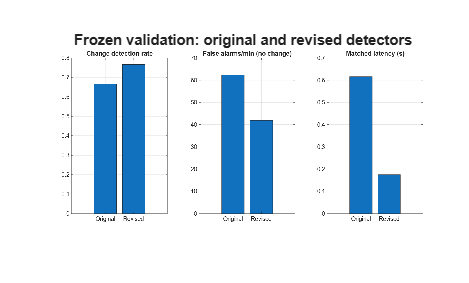


showCommittedFigure(fullfile(revisionRoot, 'validation_detectors.png'), ...
    'Frozen validation: original and revised detectors');

## Why False Alarms Matter

A false alarm means that the detector declares an acoustic change when the scheduled scene did not change. This may make the controller update its noise estimate too quickly and treat speech energy as noise. No-change controls were added so that lower latency could not be achieved simply by triggering more often.

byCondition = readtable(fullfile(revisionRoot, 'validation_by_condition.csv'), ...
    'TextType', 'string');
controlNames = ["clean_control", "stationary_office", "stationary_traffic"];
controlAudit = byCondition(ismember(byCondition.condition, controlNames), ...
    {'method', 'condition', 'false_alarms_per_minute'});
controlAudit.Properties.VariableNames = {'Method', 'ControlCondition', ...
    'FalseAlarmsPerMinute'};
controlAudit

controlAudit = 6×3 table
         Method            ControlCondition      FalseAlarmsPerMinute
    _________________    ____________________    ____________________

    "legacy_combined"    "clean_control"                65.714       
    "legacy_combined"    "stationary_office"            65.714       
    "legacy_combined"    "stationary_traffic"           55.714       
    "revised"            "clean_control"                98.571       
    "revised"            "stationary_office"            27.143       
    "revised"            "stationary_traffic"                0       


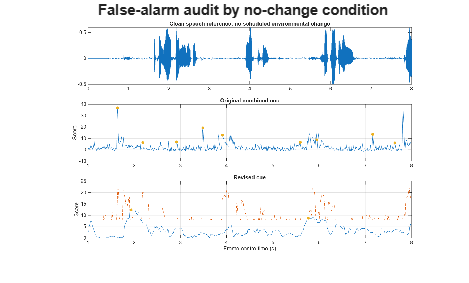


showCommittedFigure(fullfile(revisionRoot, 'validation_false_alarm_audit.png'), ...
    'False-alarm audit by no-change condition');


% The revised detector reduced false alarms overall in stationary office and
% traffic controls, but clean-speech-only false alarms increased. It is therefore
% an informative experiment rather than a replacement for the main controller.

## Did the Complete Enhancer Improve?

**Not yet.** Better event detection did not automatically produce better speech enhancement. This is the main negative result and is kept deliberately.

enhancement = readtable( ...
    fullfile(revisionRoot, 'validation_enhancement_summary.csv'), ...
    'TextType', 'string');
displaySystems = ["noisy", "fixed", "snr", "legacy_combined", "revised", "oracle"];
enhancement = enhancement(ismember(enhancement.system, displaySystems), :);
[~, order] = ismember(enhancement.system, displaySystems);
[~, order] = sort(order);
enhancement = enhancement(order, :);
enhancementResults = enhancement(:, {'system', 'mean_whole_si_sdr_db', ...
    'mean_stoi', 'mean_transition_si_sdr_db'});
enhancementResults.Properties.VariableNames = {'System', 'WholeSISDR_dB', ...
    'STOI', 'TransitionSISDR_dB'};
enhancementResults

enhancementResults = 6×4 table
         System          WholeSISDR_dB     STOI      TransitionSISDR_dB
    _________________    _____________    _______    __________________

    "noisy"                 1.1671        0.83592         -2.6967      
    "fixed"                 3.2733         0.8312          1.2182      
    "snr"                   3.3616        0.83042           1.169      
    "legacy_combined"        4.507        0.83446          2.0723      
    "revised"               3.6119        0.83108          1.9776      
    "oracle"                3.5998        0.83079          1.9588      



fprintf(['The revised detector improved detector-level measurements, but its ' ...
    'complete enhancer produced lower whole-signal SI-SDR and STOI than the ' ...
    'original combined controller. Detector quality and enhancement quality ' ...
    'must therefore be analysed separately.\n']);

The revised detector improved detector-level measurements, but its complete enhancer produced lower whole-signal SI-SDR and STOI than the original combined controller. Detector quality and enhancement quality must therefore be analysed separately.


## Historical Pilot: Transition-Centred Evidence

The earlier pilot is retained as provenance. It showed why transition-centred analysis is useful, but it used a different protocol and a startup procedure later found not to be fully causal. Its values must not be compared directly with the latest detector audit.

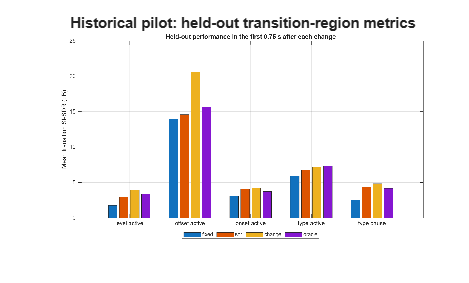

showCommittedFigure(fullfile(resultsRoot, 'held_out_transition_metrics.png'), ...
    'Historical pilot: held-out transition-region metrics');

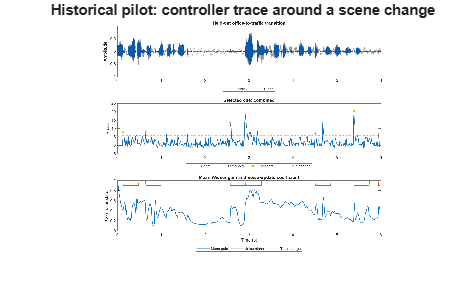


showCommittedFigure(fullfile(resultsRoot, 'held_out_controller_trace.png'), ...
    'Historical pilot: controller trace around a scene change');

## Detector-Cue Ablation

Log-spectrum change, spectral flux, short-time modulation, and a combined cue were evaluated independently. This ablation tests whether the modulation term contributes useful evidence instead of assuming that a more complicated score is automatically better.

ablation = readtable(fullfile(resultsRoot, 'detector_ablation_summary.csv'), ...
    'TextType', 'string');
ablation

ablation = 8×9 table
        split              cue          GroupCount    mean_detected_within_1_5_s    std_detected_within_1_5_s    mean_detection_latency_s    std_detection_latency_s    mean_false_alarms_before_change    std_false_alarms_before_change
    _____________    _______________    __________    __________________________    _________________________    ________________________    _______________________    _______________________________    ______________________________

    "development"    "combined"             15                     0.6                       0.50709                      0.9392                     0.95305                            2.8                            1.0142            
    "development"    "log_spectrum"         15                 0.46667                        0.5164                      1.2246                      1.2548                         2.3333                            0.9759            
    "development"    "modulation"         

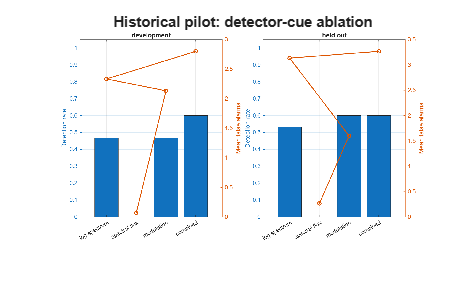


showCommittedFigure(fullfile(resultsRoot, 'detector_ablation.png'), ...
    'Historical pilot: detector-cue ablation');

## Speech-Distortion and Noise-Suppression Trade-off

The saved Wiener gain is also applied separately to clean-speech and noise components. This reveals whether an apparent improvement comes from stronger noise suppression, greater speech damage, or both.

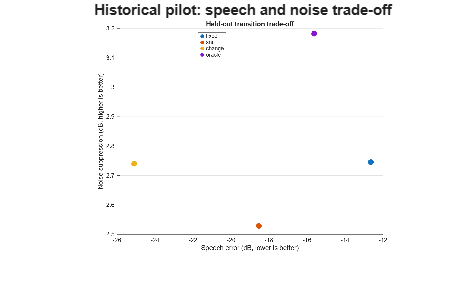

showCommittedFigure(fullfile(resultsRoot, 'speech_noise_tradeoff.png'), ...
    'Historical pilot: speech and noise trade-off');

## Listening Examples

The repository contains aligned WAV examples for clean speech, the dynamic noisy mixture, fixed Wiener, change-aware Wiener, and oracle Wiener. They are listed here but are not played automatically when this document runs.

audioFolder = fullfile(resultsRoot, 'audio');
audioFiles = ["clean.wav"; "dynamic_noisy.wav"; "fixed_wiener.wav"; ...
    "change_aware_wiener.wav"; "oracle_wiener.wav"];
audioAvailable = isfile(fullfile(audioFolder, audioFiles));
listeningExamples = table(audioFiles, audioAvailable, ...
    'VariableNames', {'File', 'Available'});
listeningExamples

listeningExamples = 5×2 table
              File               Available
    _________________________    _________

    "clean.wav"                    true   
    "dynamic_noisy.wav"            true   
    "fixed_wiener.wav"             true   
    "change_aware_wiener.wav"      true   
    "oracle_wiener.wav"            true   



% To listen to one example in MATLAB, remove the comment marker below:
%
% |[y, fs] = audioread(fullfile(audioFolder, 'change_aware_wiener.wav')); soundsc(y, fs);|

## Automated Checks and Reproduction

The committed results are accompanied by tests for requested SNR, output validity, scene metadata, controller modes, and causal detector behaviour. From the repository root, the main commands are:

`addpath('src'); run('tests/run_tests.m');`

`addpath('src'); run('src/run_transition_demo.m');`

`addpath('src'); run('src/run_full_transition_study.m');`

`addpath('src'); run('src/run_detector_revision.m');`

The first two can run without the full real-data study. The real-data scripts require the official VoiceBank and DEMAND files described in `data/README.md`.

## Current Conclusions

1. Whole-utterance scores can hide short failures after an acoustic change. 2. A common Wiener pipeline makes controller comparisons easier to interpret. 3. The revised cue improved hit rate, latency, and aggregate no-change false alarms in the frozen audit. 4. The revised complete enhancer did not outperform the original controller. 5. Clean-speech false alarms and the small dataset remain the main weaknesses.

The current project is therefore a reproducible preliminary investigation, not a claim of state-of-the-art enhancement.

## Next Steps

1. Diagnose speech-driven false alarms without changing the validation set. 2. Study how detector events alter noise-PSD tracking and Wiener gain recovery. 3. Add more speakers, noises, transition pairs, and repeated seeds. 4. Freeze one final configuration and report paired confidence intervals. 5. Complete the final report, video, and GitHub Pages narrative.

fprintf('Summary completed successfully. All displayed evidence came from committed result files.\n');

Summary completed successfully. All displayed evidence came from committed result files.


## Local display helper

function showCommittedFigure(fileName, figureTitle)
%SHOWCOMMITTEDFIGURE Display a saved result without recomputing the experiment.
    figure('Color', 'w', 'Name', figureTitle);
    image(imread(fileName));
    axis image off;
    title(figureTitle, 'Interpreter', 'none');
end

function name = getLastPathPart(folder)
%GETLASTPATHPART Return the final folder name without changing directories.
    [~, name] = fileparts(folder);
end